# Denavit - Hartenberg Kinematics

clear; clc; close all;
syms t q1t(t) q2t(t) q3t(t) q1 q2 q3 q1p q2p q3p;

load_robot_data;

## Direct Kinematics & Dynamics

% DH parameters and geometrical properties
nLinks = 4; % considering the base as first link
D=[l1a l1c+l2 0]; A=[l1b 0 l3]; T=[0 pi/2 -pi/2]; F=[+pi/2 -pi/2 -pi/2];
alpha=angle;
P3e=[0;0;0;1];

DHpar=[q1+T(1)  D(1)     A(1)   F(1)-alpha;
       T(2)     q2+D(2)  A(2)   F(2);
       q3+T(3)  D(3)     A(3)   F(3)];

DH_bary_par=[q1+T(1)  D(1)-abs(G1(2))-abs(G1(3))*sin(alpha)   A(1)-abs(G1(1))  F(1)-alpha;
             T(2)     q2+D(2)-abs(g2)                         A(2)             F(2);
             q3+T(3)  D(3)                                    A(3)-abs(g3)     F(3)];

% Define symbolic matrix
[M01sym,M12sym,M23sym,M03sym] = DH_total_matrix(DHpar)

$$M01sym = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\frac{\sin\left(q_{1}\right)}{2} & \frac{\sqrt{3}\,\sin\left(q_{1}\right)}{2} & \frac{139\,\cos\left(q_{1}\right)}{500}\\ \sin\left(q_{1}\right) & \frac{\cos\left(q_{1}\right)}{2} & -\frac{\sqrt{3}\,\cos\left(q_{1}\right)}{2} & \frac{139\,\sin\left(q_{1}\right)}{500}\\ 0 & \frac{\sqrt{3}}{2} & \frac{1}{2} & \frac{27}{100}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$M12sym = \left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ 1 & 0 & 0 & 0\\ 0 & -1 & 0 & q_{2}+\frac{73}{100}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$M23sym = \left(\begin{array}{cccc} \cos\left(q_{3}-\frac{\pi }{2}\right) & 0 & -\sin\left(q_{3}-\frac{\pi }{2}\right) & \frac{299\,\cos\left(q_{3}-\frac{\pi }{2}\right)}{1000}\\ \sin\left(q_{3}-\frac{\pi }{2}\right) & 0 & \cos\left(q_{3}-\frac{\pi }{2}\right) & \frac{299\,\sin\left(q_{3}-\frac{\pi }{2}\right)}{1000}\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$M03sym = \begin{array}{l} \left(\begin{array}{cccc} -\frac{\sigma_{2}\,\sin\left(q_{1}\right)}{2}-\frac{\sqrt{3}\,\sin\left(q_{1}\right)\,\sigma_{1}}{2} & \cos\left(q_{1}\right) & \frac{\sin\left(q_{1}\right)\,\sigma_{1}}{2}-\frac{\sqrt{3}\,\sigma_{2}\,\sin\left(q_{1}\right)}{2} & \frac{139\,\cos\left(q_{1}\right)}{500}-\frac{299\,\sigma_{2}\,\sin\left(q_{1}\right)}{2000}+\frac{\sqrt{3}\,\sin\left(q_{1}\right)\,\left(q_{2}+\frac{73}{100}\right)}{2}-\frac{299\,\sqrt{3}\,\sin\left(q_{1}\right)\,\sigma_{1}}{2000}\\ \frac{\cos\left(q_{1}\right)\,\sigma_{2}}{2}+\frac{\sqrt{3}\,\cos\left(q_{1}\right)\,\sigma_{1}}{2} & \sin\left(q_{1}\right) & \frac{\sqrt{3}\,\cos\left(q_{1}\right)\,\sigma_{2}}{2}-\frac{\cos\left(q_{1}\right)\,\sigma_{1}}{2} & \frac{139\,\sin\left(q_{1}\right)}{500}+\frac{299\,\cos\left(q_{1}\right)\,\sigma_{2}}{2000}-\frac{\sqrt{3}\,\cos\left(q_{1}\right)\,\left(q_{2}+\frac{73}{100}\right)}{2}+\frac{299\,\sqrt{3}\,\cos\left(q_{1}\right)\,\sigma_{1}}{2000}\\ \frac{\sqrt{3}\,\sigma_{2}}{2}-\frac{\sigma_{1}}{2} & 0 & -\frac{\sigma_{2}}{2}-\frac{\sqrt{3}\,\sigma_{1}}{2} & \frac{q_{2}}{2}-\frac{299\,\sigma_{1}}{2000}+\frac{299\,\sqrt{3}\,\sigma_{2}}{2000}+\frac{127}{200}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{3}-\frac{\pi }{2}\right)\\ \sigma_{2}=\cos\left(q_{3}-\frac{\pi }{2}\right) \end{array}$$

[~,~,~,M03(q1,q2,q3)] = DH_total_matrix(DHpar);
M01 = matlabFunction(M01sym,'Vars',[q1 q2 q3]);
M12 = matlabFunction(M12sym,'Vars',[q1 q2 q3]);
M23 = matlabFunction(M23sym,'Vars',[q1 q2 q3]);
M03mlf = matlabFunction(M03,'Vars',[q1 q2 q3]);

Mall = {M01;M12;M23};

DHdirect = M03*P3e; % Direct kinematics function
DHdirect = matlabFunction(DHdirect,'Vars',[q1 q2 q3]);

% Position of the gripper in the reference system 0 at the initial conditions 
P0e_0=DHdirect(0,0,0)

P0e_0 =     0.2780
   -0.8911
    0.7845
    1.0000



% Matrici baricentri
[M01_Gsym,M12_Gsym,M23_Gsym,M03_G(q1,q2,q3)] = DH_total_matrix(DH_bary_par)

$$M01\_Gsym = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\frac{\sin\left(q_{1}\right)}{2} & \frac{\sqrt{3}\,\sin\left(q_{1}\right)}{2} & \frac{99\,\cos\left(q_{1}\right)}{1000}\\ \sin\left(q_{1}\right) & \frac{\cos\left(q_{1}\right)}{2} & -\frac{\sqrt{3}\,\cos\left(q_{1}\right)}{2} & \frac{99\,\sin\left(q_{1}\right)}{1000}\\ 0 & \frac{\sqrt{3}}{2} & \frac{1}{2} & \frac{43}{250}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$M12\_Gsym = \left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ 1 & 0 & 0 & 0\\ 0 & -1 & 0 & q_{2}+\frac{441029549746527791}{900719925474099200}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$M23\_Gsym = \left(\begin{array}{cccc} \cos\left(q_{3}-\frac{\pi }{2}\right) & 0 & -\sin\left(q_{3}-\frac{\pi }{2}\right) & \frac{4591571449766547\,\cos\left(q_{3}-\frac{\pi }{2}\right)}{36028797018963968}\\ \sin\left(q_{3}-\frac{\pi }{2}\right) & 0 & \cos\left(q_{3}-\frac{\pi }{2}\right) & \frac{4591571449766547\,\sin\left(q_{3}-\frac{\pi }{2}\right)}{36028797018963968}\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$M03\_G(q1, q2, q3) = \begin{array}{l} \left(\begin{array}{cccc} -\frac{\sigma_{2}\,\sin\left(q_{1}\right)}{2}-\frac{\sqrt{3}\,\sin\left(q_{1}\right)\,\sigma_{1}}{2} & \cos\left(q_{1}\right) & \frac{\sin\left(q_{1}\right)\,\sigma_{1}}{2}-\frac{\sqrt{3}\,\sigma_{2}\,\sin\left(q_{1}\right)}{2} & \frac{99\,\cos\left(q_{1}\right)}{1000}-\frac{4591571449766547\,\sigma_{2}\,\sin\left(q_{1}\right)}{72057594037927936}+\frac{\sqrt{3}\,\sin\left(q_{1}\right)\,\left(q_{2}+\frac{441029549746527791}{900719925474099200}\right)}{2}-\frac{4591571449766547\,\sqrt{3}\,\sin\left(q_{1}\right)\,\sigma_{1}}{72057594037927936}\\ \frac{\cos\left(q_{1}\right)\,\sigma_{2}}{2}+\frac{\sqrt{3}\,\cos\left(q_{1}\right)\,\sigma_{1}}{2} & \sin\left(q_{1}\right) & \frac{\sqrt{3}\,\cos\left(q_{1}\right)\,\sigma_{2}}{2}-\frac{\cos\left(q_{1}\right)\,\sigma_{1}}{2} & \frac{99\,\sin\left(q_{1}\right)}{1000}+\frac{4591571449766547\,\cos\left(q_{1}\right)\,\sigma_{2}}{72057594037927936}-\frac{\sqrt{3}\,\cos\left(q_{1}\right)\,\left(q_{2}+\frac{441029549746527791}{900719925474099200}\right)}{2}+\frac{4591571449766547\,\sqrt{3}\,\cos\left(q_{1}\right)\,\sigma_{1}}{72057594037927936}\\ \frac{\sqrt{3}\,\sigma_{2}}{2}-\frac{\sigma_{1}}{2} & 0 & -\frac{\sigma_{2}}{2}-\frac{\sqrt{3}\,\sigma_{1}}{2} & \frac{q_{2}}{2}-\frac{4591571449766547\,\sigma_{1}}{72057594037927936}+\frac{4591571449766547\,\sqrt{3}\,\sigma_{2}}{72057594037927936}+\frac{3754386020548089579}{9007199254740992000}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{3}-\frac{\pi }{2}\right)\\ \sigma_{2}=\cos\left(q_{3}-\frac{\pi }{2}\right) \end{array}$$

M01_G = matlabFunction(M01sym,'Vars',[q1 q2 q3]);
M12_G = matlabFunction(M12sym,'Vars',[q1 q2 q3]);
M23_G = matlabFunction(M23sym,'Vars',[q1 q2 q3]);
Mall_G = {M01_G;M12_G;M23_G};

#### Check W and H matrices

DHpar_t=[q1t(t)+T(1)   D(1)          A(1)   F(1)-alpha;
        T(2)          q2t(t)+D(2)   A(2)   F(2);
        q3t(t)+T(3)   D(3)          A(3)   F(3)];
    
[M01_t,M12_t,M23_t] = DH_total_matrix(DHpar_t);

% Link 1
M01p=diff(M01_t,t);
W01_t=M01p*M01_t^-1;
W01=subs(W01_t,[diff(q1t(t),t), diff(q2t(t),t), diff(q3t(t),t), q1t(t), q2t(t), q3t(t)],[q1p q2p q3p q1 q2 q3]);
W01=simplify(W01)

$$W01 = \left(\begin{array}{cccc} 0 & -\mathrm{q1p} & 0 & 0\\ \mathrm{q1p} & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

W01_mlf = matlabFunction(W01,'Vars',[q1p q2p q3p]);

% Link 2
M12p=diff(M12_t,t);
W12_t=M12p*M12_t^-1;
W12=subs(W12_t,[diff(q1t(t),t), diff(q2t(t),t), diff(q3t(t),t), q1t(t), q2t(t), q3t(t)],[q1p q2p q3p q1 q2 q3]);
W12=simplify(W12)

$$W12 = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \mathrm{q2p}\\ 0 & 0 & 0 & 0 \end{array}\right)$$

W12_mlf = matlabFunction(W12,'Vars',[q1p q2p q3p]);

% Link 3
M23p=diff(M23_t,t);
W23_t=M23p*M23_t^-1;
W23=subs(W23_t,[diff(q1t(t),t), diff(q2t(t),t), diff(q3t(t),t), q1t(t), q2t(t), q3t(t)],[q1p q2p q3p q1 q2 q3]);
W23=simplify(W23)

$$W23 = \left(\begin{array}{cccc} 0 & -\mathrm{q3p} & 0 & 0\\ \mathrm{q3p} & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

W23_mlf = matlabFunction(W23,'Vars',[q1p q2p q3p]);

### Call inverse kinematics W & H

% kinematics_initialization_matrix;
% inverse_kinematics_WH;

### Workspace

% DH_workspace;

### Naming convention

Xab_c → matrix of b wrt a in reference frame c

XX_c → array of X matrices in reference frame c

M → position matrix of a reference frame

W → velocity matrix of a reference frame

H → acceleration matrix of a reference frame

Mg → position matrix of a reference frame put in the center of mass of a link

GRIPPER SPACE → x-y-z

JOINT SPACE → q1-q2-q3

### First task

#### Data of the problem

Preliminary operations.

% COMPUTE TRAJECTORY FOR THE 2ND TASK
nPoints_spline = 100;   dilation_factor = 0.35;
x_tilt = deg2rad(45);   y_tilt = deg2rad(65);   z_tilt = deg2rad(10);
x_offset = 0.95;        y_offset = 0.3;         z_offset = 0.8;

spline_points_target = compute_trajectory(nPoints_spline,dilation_factor, ...
                                          x_tilt,y_tilt,z_tilt, ...
                                          x_offset,y_offset,z_offset);
                                      

Evaluate symbolic jacobian and its temporal derivative.

syms l1a l1b l1c l2 l3 tilt_angle ...
     q1_sym(t) q2_sym(t) q3_sym(t) ...
     q1p_sym(t) q2p_sym(t) q3p_sym(t)
Qsymb = [l1a; l1b; l1c; l2; l3; tilt_angle; ...
         q1_sym(t); q2_sym(t); q3_sym(t)];
Qp_symb = [l1a; l1b; l1c; l2; l3; tilt_angle; ...
           q1_sym(t); q2_sym(t); q3_sym(t); ...
           q1p_sym(t); q2p_sym(t); q3p_sym(t)];

[J_symb,~] = jac_symb;
[Jp_symb,~] = jacP_symb;   

disp("%%%%%%%%%%%%%%%%%%%%%% FIRST TASK %%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%% FIRST TASK %%%%%%%%%%%%%%%%%%%%%%


task=1;

% HOME AND TARGET POSITIONS
% Starting point
Q_home = {0; 0; 0};
[S_home,~] = dir_kin(Q_home,L,angle);

S_home = cell2mat(S_home);
S_initial_shape = spline_points_target(1:3,1);
S_shape = [spline_points_target(1:3,1) spline_points_target(1:3,:) spline_points_target(1:3,end);]; % To assure start and end null velocity
S_final_shape = spline_points_target(1:3,end);

Q_home = cell2mat(Q_home);

% Final point
Q0_initial_shape = inv_kin(num2cell(S_initial_shape),L,angle,1);
Q_initial_shape = cell2mat(inv_kin_numerical(num2cell(S_initial_shape),L,angle,Q0_initial_shape));

dQ = Q_initial_shape-Q_home;
abs_dQ = norm(dQ);


ACTUATION TIME

% Formula for the minimum actuation time in the case of cycloidal law of motion
T1_min = max([2*abs_dQ/vel_limits(2) sqrt(2*pi*abs_dQ/acc_limits(2)) sqrt(2*pi*abs_dQ/abs(acc_limits(1)))]);
T2_min = max([2*abs_dQ/vel_limits(4) sqrt(2*pi*abs_dQ/acc_limits(4)) sqrt(2*pi*abs_dQ/abs(acc_limits(3)))]);
T3_min = max([2*abs_dQ/vel_limits(6) sqrt(2*pi*abs_dQ/acc_limits(6)) sqrt(2*pi*abs_dQ/abs(acc_limits(5)))]);

% The laws are computed for the whole duration of the motion of the slowest joint
Ttot = max([T1_min T2_min T3_min]);

% Number of points in which to compute the law of motion
nPoints = 100;

#### Initialization

kinematics_initialization_matrix;
dynamics_initialization_matrix;

#### Kinematics and dynamics

each_timestep_kin_dyn_matrix;

#### Energy and power of the whole body

%%{
% TOTAL ENERGY OF THE WHOLE BODY (sum of the energy of each link)
Ek_tot = sum(Ek,1,'omitnan');
Ep_tot = sum(Ep,1,'omitnan');
E_tot = sum(E,1,'omitnan');

% TOTAL POWER OF THE WHOLE BODY (sum of the power of each link) and
% POWER OF JUST WEIGHT FORCES
Wq_tot = sum(Wq,1,'omitnan');
Wext_tot = Wext;
W_tot = sum(W,1,'omitnan');
W_tot_plus_weight = W_tot+sum(Wweight,1,'omitnan');
%}

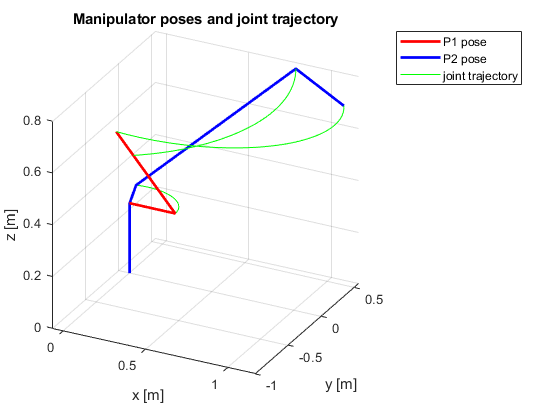

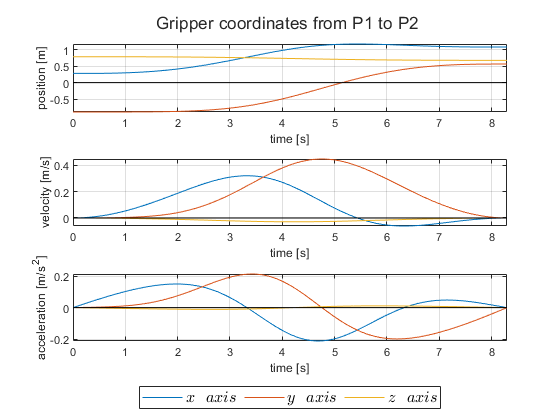

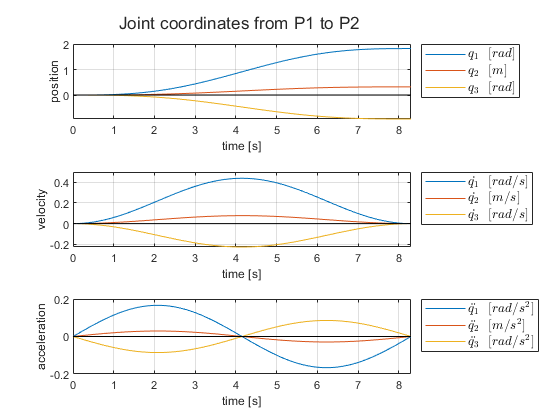

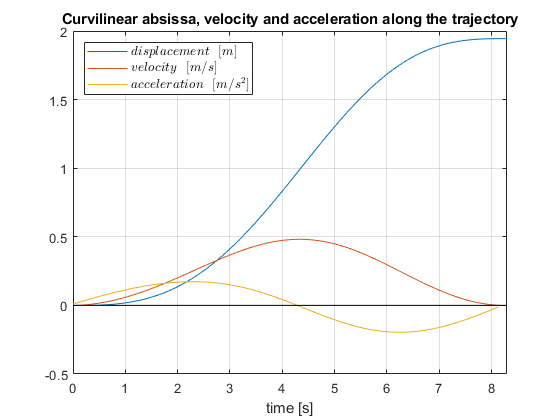

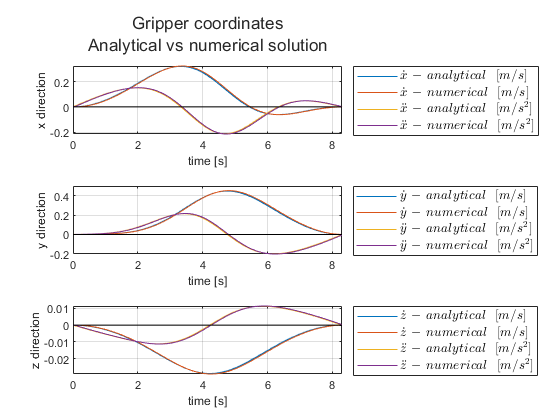

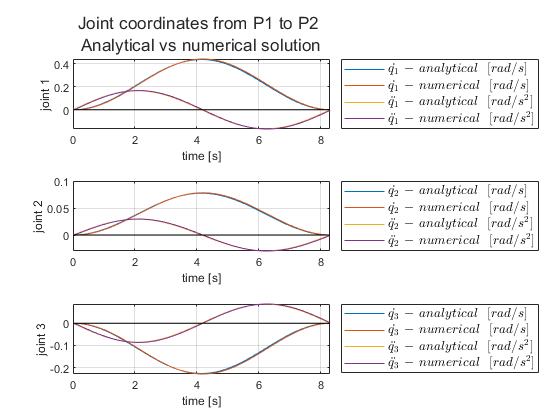

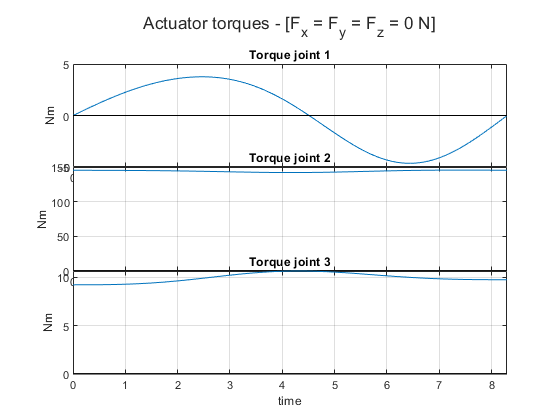

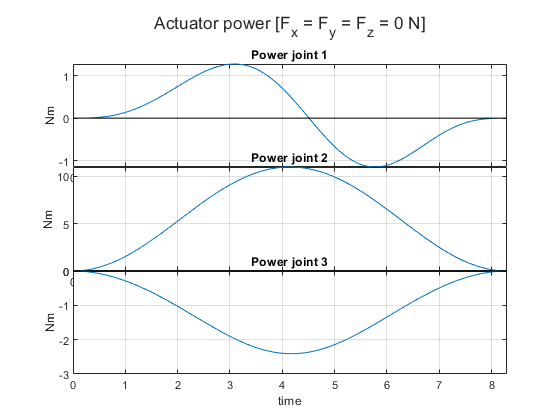

fsz = 11

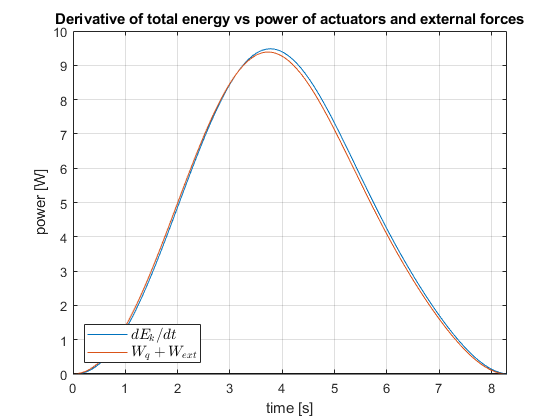

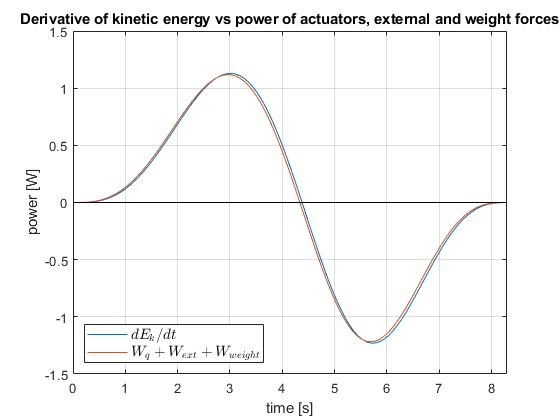

differential_calculation_matrix;
plot_kin_dyn_results_matrix;

### Second task

clear Q
disp("%%%%%%%%%%%%%%%%%%%%%% SECOND TASK %%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%% SECOND TASK %%%%%%%%%%%%%%%%%%%%%%


task=2;

Number of points in which to compute the law of motion: is the number of interpolation points obtained with the spline.

nPoints = size(S_shape,2);
inverse_kinematics_WH;

Sp = struct with fields:
    q1p: [1×1 sym]
    q2p: [1×1 sym]
    q3p: [1×1 sym]


$$q1p\_Sp = \frac{2000\,\left(556\,\mathrm{yp}\,{\cos\left(q_{1}\right)}^{2}-556\,\mathrm{yp}-278\,\mathrm{xp}\,\sin\left(2\,q_{1}\right)+730\,\sqrt{3}\,\mathrm{xp}\,{\cos\left(q_{1}\right)}^{2}+365\,\sqrt{3}\,\mathrm{yp}\,\sin\left(2\,q_{1}\right)-299\,\mathrm{xp}\,{\cos\left(q_{1}\right)}^{2}\,\sin\left(q_{3}\right)+299\,\sqrt{3}\,\mathrm{xp}\,{\cos\left(q_{1}\right)}^{2}\,\cos\left(q_{3}\right)-299\,\mathrm{yp}\,\cos\left(q_{1}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+1000\,\sqrt{3}\,q_{2}\,\mathrm{xp}\,{\cos\left(q_{1}\right)}^{2}+500\,\sqrt{3}\,q_{2}\,\mathrm{yp}\,\sin\left(2\,q_{1}\right)+299\,\sqrt{3}\,\mathrm{yp}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)}{1688101\,\cos\left(q_{1}\right)+3000000\,{q_{2}}^{2}\,\cos\left(q_{1}\right)+1309620\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)+166244\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+178802\,\cos\left(q_{1}\right)\,{\cos\left(q_{3}\right)}^{2}-405880\,\sqrt{3}\,\sin\left(q_{1}\right)+4380000\,q_{2}\,\cos\left(q_{1}\right)-556000\,\sqrt{3}\,q_{2}\,\sin\left(q_{1}\right)-436540\,\sqrt{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)-166244\,\sqrt{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)+1794000\,q_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)-178802\,\sqrt{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{3}\right)-598000\,\sqrt{3}\,q_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)}$$

$$q2p\_Sp = \frac{299\,\mathrm{zp}\,\sin\left(2\,q_{3}\right)-299\,\sqrt{3}\,\mathrm{zp}-299\,\mathrm{yp}\,\cos\left(q_{1}\right)+299\,\mathrm{xp}\,\sin\left(q_{1}\right)+2190\,\mathrm{zp}\,\sin\left(q_{3}\right)+730\,\sqrt{3}\,\mathrm{zp}\,\cos\left(q_{3}\right)+3000\,q_{2}\,\mathrm{zp}\,\sin\left(q_{3}\right)+598\,\sqrt{3}\,\mathrm{zp}\,{\cos\left(q_{3}\right)}^{2}-2190\,\mathrm{yp}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)-556\,\mathrm{xp}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+2190\,\mathrm{xp}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-556\,\mathrm{yp}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)-598\,\mathrm{yp}\,\cos\left(q_{1}\right)\,{\cos\left(q_{3}\right)}^{2}+598\,\mathrm{xp}\,{\cos\left(q_{3}\right)}^{2}\,\sin\left(q_{1}\right)-730\,\sqrt{3}\,\mathrm{xp}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+3000\,q_{2}\,\mathrm{xp}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)+1000\,\sqrt{3}\,q_{2}\,\mathrm{zp}\,\cos\left(q_{3}\right)+556\,\sqrt{3}\,\mathrm{xp}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)+730\,\sqrt{3}\,\mathrm{yp}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+556\,\sqrt{3}\,\mathrm{yp}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-3000\,q_{2}\,\mathrm{yp}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)+1000\,\sqrt{3}\,q_{2}\,\mathrm{yp}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)-1000\,\sqrt{3}\,q_{2}\,\mathrm{xp}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+598\,\sqrt{3}\,\mathrm{yp}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{3}\right)-598\,\sqrt{3}\,\mathrm{xp}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)}{2\,\cos\left(q_{3}\right)\,\left(598\,\cos\left(q_{3}+\frac{\pi }{6}\right)+1000\,\sqrt{3}\,q_{2}+730\,\sqrt{3}\right)}$$

$$q3p\_Sp = \frac{500\,\left(2190\,\mathrm{zp}+3000\,q_{2}\,\mathrm{zp}-556\,\mathrm{xp}\,\cos\left(q_{1}\right)+897\,\mathrm{zp}\,\cos\left(q_{3}\right)-556\,\mathrm{yp}\,\sin\left(q_{1}\right)+730\,\sqrt{3}\,\mathrm{yp}\,\cos\left(q_{1}\right)-730\,\sqrt{3}\,\mathrm{xp}\,\sin\left(q_{1}\right)-299\,\sqrt{3}\,\mathrm{zp}\,\sin\left(q_{3}\right)-299\,\mathrm{yp}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+299\,\mathrm{xp}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+1000\,\sqrt{3}\,q_{2}\,\mathrm{yp}\,\cos\left(q_{1}\right)-1000\,\sqrt{3}\,q_{2}\,\mathrm{xp}\,\sin\left(q_{1}\right)+299\,\sqrt{3}\,\mathrm{yp}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)-299\,\sqrt{3}\,\mathrm{xp}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)}{299\,\cos\left(q_{3}\right)\,\left(598\,\cos\left(q_{3}+\frac{\pi }{6}\right)+1000\,\sqrt{3}\,q_{2}+730\,\sqrt{3}\right)}$$

Spp = struct with fields:
    q1pp: [1×1 sym]
    q2pp: [1×1 sym]
    q3pp: [1×1 sym]


$$q3p\_Spp = -\frac{3000000\,{q_{2}}^{2}\,{\mathrm{q1p}}^{2}-4380000\,\mathrm{zpp}+1309620\,{\mathrm{q1p}}^{2}\,\cos\left(q_{3}\right)-6000000\,q_{2}\,\mathrm{zpp}+178802\,{\mathrm{q1p}}^{2}\,{\cos\left(q_{3}\right)}^{2}-357604\,{\mathrm{q3p}}^{2}\,{\cos\left(q_{3}\right)}^{2}+4380000\,q_{2}\,{\mathrm{q1p}}^{2}+1112000\,\mathrm{xpp}\,\cos\left(q_{1}\right)-1794000\,\mathrm{zpp}\,\cos\left(q_{3}\right)+1112000\,\mathrm{ypp}\,\sin\left(q_{1}\right)+1997237\,{\mathrm{q1p}}^{2}+357604\,{\mathrm{q3p}}^{2}-1460000\,\sqrt{3}\,\mathrm{ypp}\,\cos\left(q_{1}\right)+332488\,\mathrm{q1p}\,\mathrm{q3p}\,\cos\left(q_{3}\right)+1460000\,\sqrt{3}\,\mathrm{xpp}\,\sin\left(q_{1}\right)+598000\,\sqrt{3}\,\mathrm{zpp}\,\sin\left(q_{3}\right)-436540\,\sqrt{3}\,{\mathrm{q1p}}^{2}\,\sin\left(q_{3}\right)-873080\,\sqrt{3}\,{\mathrm{q3p}}^{2}\,\sin\left(q_{3}\right)+1794000\,q_{2}\,{\mathrm{q1p}}^{2}\,\cos\left(q_{3}\right)+598000\,\mathrm{ypp}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)-598000\,\mathrm{xpp}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)-1112000\,\sqrt{3}\,\mathrm{q1p}\,\mathrm{q2p}-89401\,\sqrt{3}\,{\mathrm{q1p}}^{2}\,\sin\left(2\,q_{3}\right)-178802\,\sqrt{3}\,{\mathrm{q3p}}^{2}\,\sin\left(2\,q_{3}\right)-2000000\,\sqrt{3}\,q_{2}\,\mathrm{ypp}\,\cos\left(q_{1}\right)+332488\,\sqrt{3}\,\mathrm{q1p}\,\mathrm{q3p}\,\sin\left(q_{3}\right)+2000000\,\sqrt{3}\,q_{2}\,\mathrm{xpp}\,\sin\left(q_{1}\right)-598000\,\sqrt{3}\,\mathrm{ypp}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)-598000\,\sqrt{3}\,q_{2}\,{\mathrm{q1p}}^{2}\,\sin\left(q_{3}\right)-1196000\,\sqrt{3}\,q_{2}\,{\mathrm{q3p}}^{2}\,\sin\left(q_{3}\right)+598000\,\sqrt{3}\,\mathrm{xpp}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)}{1196\,\cos\left(q_{3}\right)\,\left(598\,\cos\left(q_{3}+\frac{\pi }{6}\right)+1000\,\sqrt{3}\,q_{2}+730\,\sqrt{3}\right)}$$

Compute sampling time in order to respect velocity and acceleration constraints of the joints.

Q0_final_shape = inv_kin(num2cell(S_final_shape),L,angle,1);
Q_final_shape = cell2mat(inv_kin_numerical(num2cell(S_final_shape),L,angle,Q0_final_shape));

matrix_2nd_Task;

dT = 0.1200

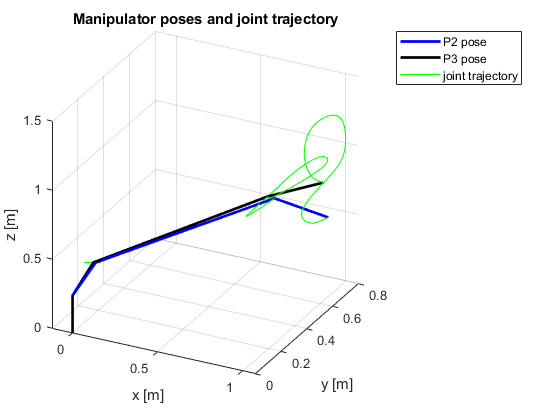

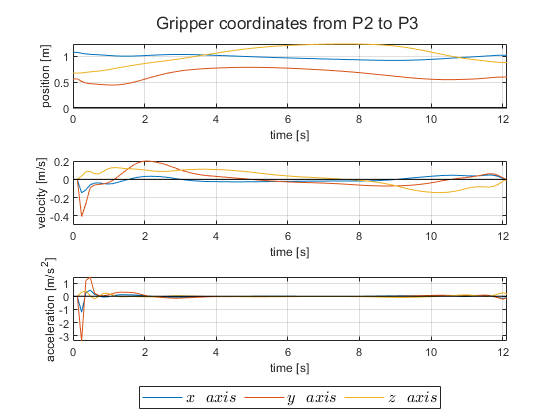

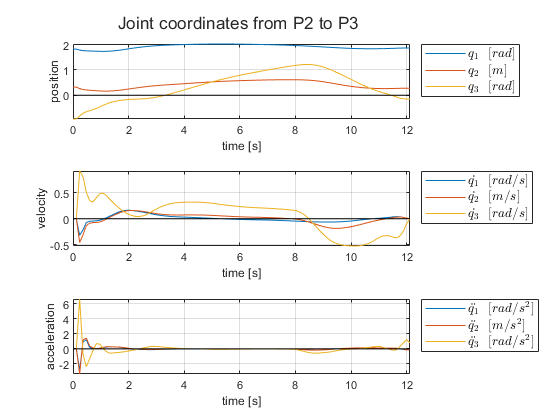

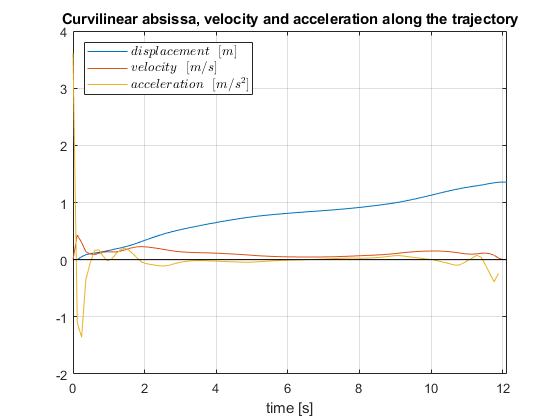

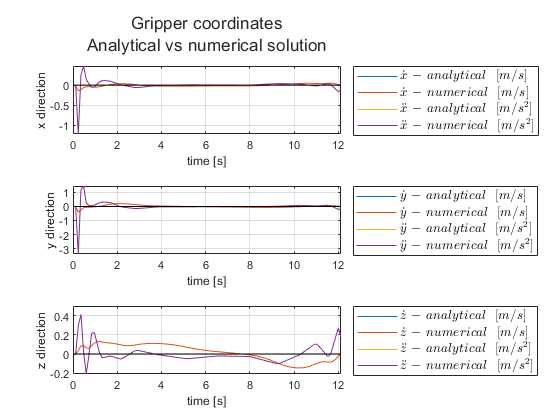

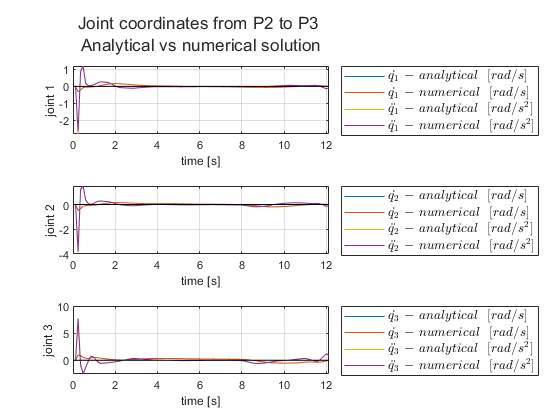

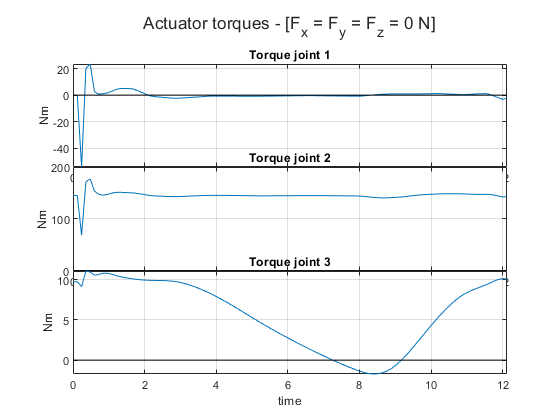

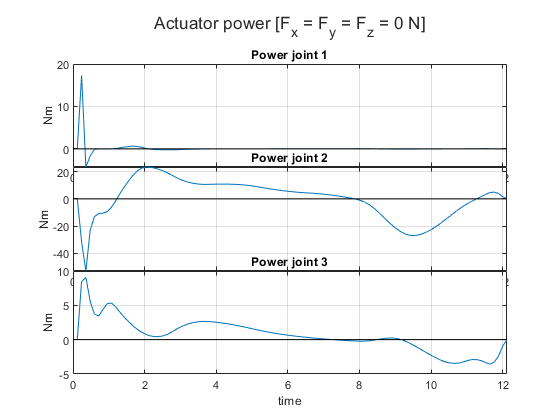

fsz = 11

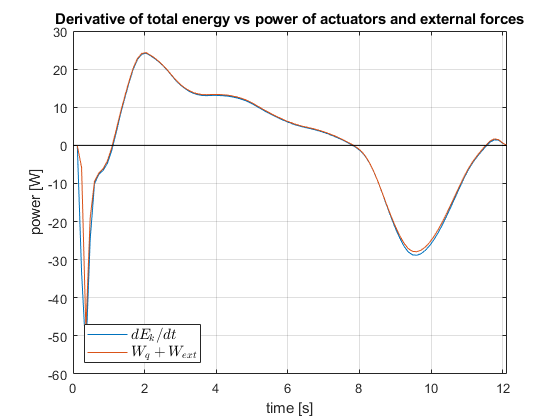

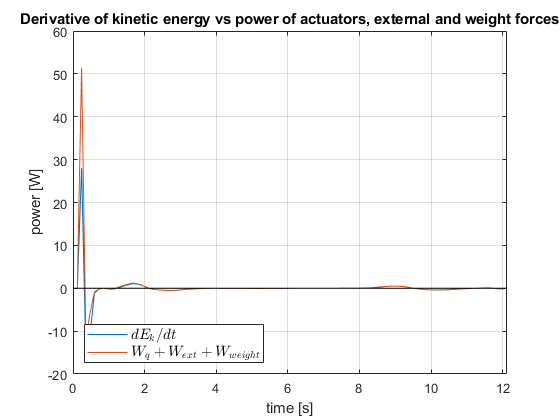

kinematics_initialization_matrix;
dynamics_initialization_matrix;
each_timestep_kin_dyn_matrix;

%%{
% TOTAL ENERGY OF THE WHOLE BODY (sum of the energy of each link)
Ek_tot = sum(Ek,1,'omitnan');
Ep_tot = sum(Ep,1,'omitnan');
E_tot = sum(E,1,'omitnan');

% TOTAL POWER OF THE WHOLE BODY (sum of the power of each link) and
% POWER OF JUST WEIGHT FORCES
Wq_tot = sum(Wq,1,'omitnan');
Wext_tot = Wext;
W_tot = sum(W,1,'omitnan');
W_tot_plus_weight = W_tot+sum(Wweight,1,'omitnan');
%}

differential_calculation_matrix;
plot_kin_dyn_results_matrix;

### Third task

Home and target positions.

% clear Phi_vinc_array_0 phi_actuators_array_0 actuatorPower clear Wq
disp("%%%%%%%%%%%%%%%%%%%%%% THIRD TASK %%%%%%%%%%%%%%%%%%%%%%")
task=3;
nPoints = 100;

dQ = Q_home-Q_final_shape;
abs_dQ = norm(dQ);

% Formula for the minimum actuation time in the case of cycloidal law of motion
T1_min = max([2*abs_dQ/vel_limits(2) sqrt(2*pi*abs_dQ/acc_limits(2)) sqrt(2*pi*abs_dQ/abs(acc_limits(1)))]);
T2_min = max([2*abs_dQ/vel_limits(4) sqrt(2*pi*abs_dQ/acc_limits(4)) sqrt(2*pi*abs_dQ/abs(acc_limits(3)))]);
T3_min = max([2*abs_dQ/vel_limits(6) sqrt(2*pi*abs_dQ/acc_limits(6)) sqrt(2*pi*abs_dQ/abs(acc_limits(5)))]);

% The laws are computed for the whole duration of the motion of the slowest joint
Ttot = max([T1_min T2_min T3_min]);

kinematics_initialization_matrix;
dynamics_initialization_matrix;
each_timestep_kin_dyn_matrix;

%%{
% TOTAL ENERGY OF THE WHOLE BODY (sum of the energy of each link)
Ek_tot = sum(Ek,1,'omitnan');
Ep_tot = sum(Ep,1,'omitnan');
E_tot = sum(E,1,'omitnan');

% TOTAL POWER OF THE WHOLE BODY (sum of the power of each link) and
% POWER OF JUST WEIGHT FORCES
Wq_tot = sum(Wq,1,'omitnan');
Wext_tot = Wext;
W_tot = sum(W,1,'omitnan');
W_tot_plus_weight = W_tot+sum(Wweight,1,'omitnan');
%}

differential_calculation_matrix;
plot_kin_dyn_results_matrix;

## Inverse Kinematics

### Initial position test

figure
plot3(P0e_0(1),P0e_0(2),P0e_0(3),'*r')
hold on

Inverse kinematics: 

Q_0 = DHinv(P0e_0,D,A,alpha);
count=0;
for i=1:2   
        P0(i,:)=DHdirect(Q_0(i,1),Q_0(i,2),Q_0(i,3));
    
    if count==0
        plot3(P0(i,1),P0(i,2),P0(i,3),'sg')
    else
        plot3(P0(i,1),P0(i,2),P0(i,3),'.b')
    end

    err(i) = norm(P0(i,:)-P0e_0');
    if err(i)<10^-10
        err(i)=0; 
    end
    count=count+1;
end
err
hold off; grid on;
xlabel('x'); ylabel('y'); zlabel('z')
title('Inv. Kin. Check')
% set(gcf,'Visible','on')

Check robot position

for i=1:size(Q_0,1)
    figure
    DH_plot_robot(Q_0(i,:),D,A,alpha,gcf,P0e_0)
    grid on
    axis equal
    view(90,0)
    xlabel('x'); ylabel('y'); zlabel('z')
    title(['Robot configuration n. ',num2str(i)])
%     set(gcf,'Visible','on')
end

### General position

Dati dei valori di q (Qi), ricavo il corrispondente punto (Pi) con la cinematica diretta.

Qi=[0.5*pi 3 pi/4];
Pi=DHdirect(Qi(1),Qi(2),Qi(3))';

Partendo da un punto Pi, calcolo i valori di q corrispondenti con la cinematica inversa (Qf). Da Qf ricalcolo, poi, Pf con la cinematica diretta. 

Confronto Pf con Pi.

Qf = DHinv(Pi,D,A,alpha);
for i=1:size(Qf,1)
    Pf(i,:)=DHdirect(Qf(i,1),Qf(i,2),Qf(i,3))';
    errP(i)=norm(Pf(i,:)-Pi);
    if errP(i)<10^-10
        errP(i)=0; 
    end 
end
% Pf
% errP

Confronto le configurazioni del robot per le diverse opzioni date da Qf.

for i=1:size(Qf,1)
    figure
    DH_plot_robot(Qf(i,:),D,A,alpha,gcf,Pi)
    grid on
    axis equal
%     view(90,0)
    xlabel('x'); ylabel('y'); zlabel('z')
    title(['Robot configuration n. ',num2str(i)])
%     set(gcf,'Visible','on')
end

### Inverse W & H - method I

Inverse W.

%{
syms q1p q2p q3p xp yp zp q1 q2 q3 w

L01_0sym = L01_0;
L12_0sym = simplify(M01sym*L12_1*inv(M01sym));

M02sym = simplify(M01sym*M12sym);
L23_0sym = simplify(M02sym*L23_2*inv(M02sym));

W03_0sym=simplify(L01_0sym*q1p+L12_0sym*q2p+L23_0sym*q3p)

q3p_1=simplify((xp-sqrt(3)*sin(q1)*zp)/sin(q1)/(10+2*q1));
q3p_2=simplify((xp+sqrt(3)*cos(q1)*zp)/-cos(q1)/(10+2*q1));

q2p_1=simplify(2*zp+sqrt(3)*(4+q2)*q3p_1);
q2p_2=simplify(2*zp+sqrt(3)*(4+q2)*q3p_2);

q1p=w;

Inverse H.

syms q1pp q2pp q3pp xpp zpp

W01_0sym = simplify(L01_0sym*q1p);
W12_0sym = simplify(L12_0sym*q2p);
W23_0sym = simplify(L23_0sym*q3p);
W02_0sym = W01_0sym + W12_0sym;

H01_0sym = simplify(L01_0sym*q1pp+L01_0sym^2*q1p);
H12_0sym = simplify(L12_0sym*q2pp);
H23_0sym = simplify(L23_0sym*q3pp+L23_0sym^2*q3p);

H02_0sym = simplify(H01_0sym + 2*W01_0sym*W12_0sym + H12_0sym);
H03_0sym = simplify(H02_0sym + 2*W02_0sym*W23_0sym + H23_0sym);

Solve symolic inverse kinematic for accelerations.

xpp_RHS = (sqrt(sym(3))*q2pp*sin(q1))/2 + (q3pp*sin(q1)*(q2 + 8))/2 + sqrt(sym(3))*q2p*w*cos(q1) + (sqrt(sym(3))*q3p*sin(q1)*(q2 + 4))/2 + q3p*w*cos(q1)*(q2 + 8);
zpp_RHS = 4*q3p + q2pp/2 - 2*sqrt(sym(3))*q3pp + (q2*q3p)/2 - (sqrt(sym(3))*q2*q3pp)/2;

xpp_MLF = matlabFunction(xpp_RHS,'Vars',[q1 q2 q2p q3p q2pp q3pp w]);
zpp_MLF = matlabFunction(zpp_RHS,'Vars',[q1 q2 q2p q3p q2pp q3pp w]);

xpp_EQ = xpp == xpp_RHS;
zpp_EQ = zpp == zpp_RHS;

S = solve([xpp_EQ zpp_EQ], [q2pp q3pp]);
simplify(S.q2pp);
simplify(S.q3pp);
q2pp_MLF = matlabFunction(S.q2pp,'Vars',[q1 q2 q2p q3p w xpp zpp]);
q3pp_MLF = matlabFunction(S.q3pp,'Vars',[q1 q2 q2p q3p w xpp zpp]);
%}

### Inverse W & H - method I.I

% syms xp yp zp xpp ypp zpp q1 q2 q3 q1p q2p q3p q1pp q2pp q3pp wx wy wz
% 
% % Conversioni
% M02sym = simplify(M01sym*M12sym);
% L01_0sym = L01_0;
% L12_0sym = simplify(M01sym*L12_1*inv(M01sym));
% L23_0sym = simplify(M02sym*L23_2*inv(M02sym));
% 
% W03_0sym=simplify(L01_0sym*q1p+L12_0sym*q2p+L23_0sym*q3p);
% 

W

% P0e = simplify(M03sym*P3e);
% P0ep = W03_0sym * P0e;
% 
% xp_RHS = P0ep(1);  xp_MLF = matlabFunction(xp_RHS,'Vars',[q1 q2 q3 q1p q2p q3p]);  xp_EQ = xp == xp_RHS;
% yp_RHS = P0ep(2);  yp_MLF = matlabFunction(yp_RHS,'Vars',[q1 q2 q3 q1p q2p q3p]);  yp_EQ = yp == yp_RHS;
% zp_RHS = P0ep(3);  zp_MLF = matlabFunction(zp_RHS,'Vars',[q1 q2 q3 q1p q2p q3p]);  zp_EQ = zp == zp_RHS;
% 
% Sp = solve([xp_EQ yp_EQ zp_EQ], [q1p q2p q3p])
% 
% q1p_Sp=simplify(Sp.q1p)
% q2p_Sp=simplify(Sp.q2p)
% q3p_Sp=simplify(Sp.q3p)
% 
% q1p_MLF = matlabFunction(Sp.q1p,'Vars',[q1 q2 q3 xp yp zp]);
% q2p_MLF = matlabFunction(Sp.q2p,'Vars',[q1 q2 q3 xp yp zp]);
% q3p_MLF = matlabFunction(Sp.q3p,'Vars',[q1 q2 q3 xp yp zp]);
% Qpinv = matlabFunction([Sp.q1p;Sp.q2p;Sp.q3p],'Vars',[q1 q2 q3 xp yp zp]);

H

% W01_0sym = simplify(L01_0sym*q1p);
% W12_0sym = simplify(L12_0sym*q2p);
% W23_0sym = simplify(L23_0sym*q3p);
% W02_0sym = W01_0sym + W12_0sym;
% 
% H01_0sym = simplify(L01_0sym*q1pp+L01_0sym^2*q1p^2);
% H12_0sym = simplify(L12_0sym*q2pp);
% H23_0sym = simplify(L23_0sym*q3pp+L23_0sym^2*q3p^2);
% 
% H02_0sym = simplify(H01_0sym + 2*W01_0sym*W12_0sym + H12_0sym);
% H03_0sym = simplify(H02_0sym + 2*W02_0sym*W23_0sym + H23_0sym);
% 
% P0epp = H03_0sym * P0e;
% 
% xpp_RHS = P0epp(1);  xpp_MLF = matlabFunction(xpp_RHS,'Vars',[q1 q2 q3 q1p q2p q3p q1pp q2pp q3pp]);  xpp_EQ = xpp == xpp_RHS;
% ypp_RHS = P0epp(2);  ypp_MLF = matlabFunction(ypp_RHS,'Vars',[q1 q2 q3 q1p q2p q3p q1pp q2pp q3pp]);  ypp_EQ = ypp == ypp_RHS;
% zpp_RHS = P0epp(3);  zpp_MLF = matlabFunction(zpp_RHS,'Vars',[q1 q2 q3 q1p q2p q3p q1pp q2pp q3pp]);  zpp_EQ = zpp == zpp_RHS;
% 
% Spp = solve([xpp_EQ ypp_EQ zpp_EQ], [q1pp q2pp q3pp])
% 
% q1p_Spp=simplify(Spp.q1pp)
% q2p_Spp=simplify(Spp.q2pp)
% q3p_Spp=simplify(Spp.q3pp)
% 
% q1pp_MLF = matlabFunction(Spp.q1pp,'Vars',[q1 q2 q3 q1p q2p q3p xp yp zp xpp ypp zpp]);
% q2pp_MLF = matlabFunction(Spp.q2pp,'Vars',[q1 q2 q3 q1p q2p q3p xp yp zp xpp ypp zpp]);
% q3pp_MLF = matlabFunction(Spp.q3pp,'Vars',[q1 q2 q3 q1p q2p q3p xp yp zp xpp ypp zpp]);
% Qppinv = matlabFunction([Spp.q1pp;Spp.q2pp;Spp.q3pp],'Vars',[q1 q2 q3 q1p q2p q3p xp yp zp xpp ypp zpp]);

### Inverse W & H - method II

%{
syms xp yp zp xpp ypp zpp q1 q2 q3 q1p q2p q3p q1pp q2pp q3pp wx wy wz

P0e = simplify(M03sym*P3e);
M0aux = [[eye(3);[0 0 0]] P0e];
M1aux = simplify( inv(M01sym)*M0aux );
M2aux = simplify( inv(M02sym)*M0aux );
% M13sym = simplify(M12sym*M23sym);

L12_0sym = simplify( M01sym*L12_1*inv(M01sym) );
L23_0sym = simplify( M02sym*L23_2*inv(M02sym) );


L01_aux = simplify( inv(M0aux)*L01_0*M0aux );
L12_aux = simplify( inv(M1aux)*L12_1*M1aux );
L23_aux = simplify( inv(M2aux)*L23_2*M2aux );

% Matrice W03_aux
W03_aux=inv(M0aux)*W03_0sym*M0aux

Pp = W03_0sym*P0e

Qp_inv = [q1p; q2p; q3p];
V = [xp; yp; zp; wx; wy; wz];

T=[L01_aux*[0;0;0;1] L01_aux*[0;0;0;1] L01_aux*[0;0;0;1]]; T(end,:)=[];
T= [T;
    L01_aux(3, 2)  L12_aux(3, 2) L23_aux(3, 2);
    L01_aux(1, 3)  L12_aux(1, 3) L23_aux(1, 3);
    L01_aux(2, 1)  L12_aux(2, 1) L23_aux(2, 1)];

Tmlf= matlabFunction(T,'Vars',[q1 q2 q3]);

TQ = simplify(T*Qp_inv)

Solve the synbolic system.

xp_RHS = TQ(1);  xp_MLF = matlabFunction(xp_RHS,'Vars',[q1 q2 q3 q1p q2p q3p]);  xp_EQ = xp == xp_RHS;
yp_RHS = TQ(2);  yp_MLF = matlabFunction(xp_RHS,'Vars',[q1 q2 q3 q1p q2p q3p]);  yp_EQ = yp == yp_RHS;
zp_RHS = TQ(3);  zp_MLF = matlabFunction(xp_RHS,'Vars',[q1 q2 q3 q1p q2p q3p]);  zp_EQ = zp == zp_RHS;
wx_RHS = TQ(4);  wx_MLF = matlabFunction(xp_RHS,'Vars',[q1 q2 q3 q1p q2p q3p]);  wx_EQ = wx == wx_RHS;
wy_RHS = TQ(5);  wy_MLF = matlabFunction(xp_RHS,'Vars',[q1 q2 q3 q1p q2p q3p]);  wy_EQ = wy == wy_RHS;
wz_RHS = TQ(6);  wz_MLF = matlabFunction(xp_RHS,'Vars',[q1 q2 q3 q1p q2p q3p]);  wz_EQ = wz == wz_RHS;

% S = solve([xp_EQ yp_EQ zp_EQ wx_EQ wy_EQ wz_EQ], [q1p q2p q3p])
S = solve([xp_EQ yp_EQ zp_EQ], [q1p q2p q3p])
simplify(S.q1p)
simplify(S.q2p)

S = solve([xp_EQ], [q2p])
simplify(S.q2p)
% S = solve([wx_EQ wz_EQ], [q1p q3p])

% simplify(S.q1p)

simplify(S.q2p)
simplify(S.q3p)

q1p_MLF = matlabFunction(S.q1p,'Vars',[q1 q2 q3 xp yp zp wx wy wz]);
q2p_MLF = matlabFunction(S.q2p,'Vars',[q1 q2 q3 xp yp zp wx wy wz]);
q3p_MLF = matlabFunction(S.q3p,'Vars',[q1 q2 q3 xp yp zp wx wy wz]);
simplify(S.q2pp);
simplify(S.q3pp);
q2pp_MLF = matlabFunction(S.q2pp,'Vars',[q1 q2 q2p q3p w xpp zpp]);
q3pp_MLF = matlabFunction(S.q3pp,'Vars',[q1 q2 q2p q3p w xpp zpp]);

Test.

% define joints coordinates and gripper velocity
% V = [xp; yp; zp; wx; wy; wz];

q1=0.3*pi; q2=0.1; q3=0.2*pi;
V=[1; 2; 3; 0.2*pi; 0.1*pi; 0.3*pi];
J=Tmlf(q1,q2,q3)

Qp_inv = J\V;
%}
